素质三连

clear;
clc;
close all;

初始化网格

subnode.s1=[...
    zeros(8,1),(5:12)';
    ones(5,1),(5:9)';
    ones(5,1)*2,(5:9)';
    ones(5,1)*3,(5:9)';
    ones(5,1)*4,(5:9)'];
subnode.s2=[...
    (8:20)',ones(13,1)*4;
    (5:20)',ones(16,1)*5;
    (5:20)',ones(16,1)*6;
    (5:20)',ones(16,1)*7;
    (5:20)',ones(16,1)*8;
    (11:14)',ones(4,1)*9];
subnode.s3=[...
    ones(7,1)*21,(4:10)';
    ones(7,1)*22,(4:10)';
    ones(7,1)*23,(4:10)';
    ones(7,1)*24,(2:8)';
    ones(7,1)*25,(2:8)';
    ones(7,1)*26,(2:8)';
    ones(7,1)*27,(2:8)';
    ones(7,1)*28,(2:8)'];
subnode.s4=[...
    (29:50)',ones(22,1)*3;
    (29:73)',ones(45,1)*4;
    (29:73)',ones(45,1)*5;
    (29:73)',ones(45,1)*6];
subnode.s5=[...
    (74:90)',ones(17,1)*4;
    (74:90)',ones(17,1)*5;
    (74:90)',ones(17,1)*6;
    [81:83,88:90]',ones(6,1)*7];
subnode.s6=[...
    (89:99)',ones(11,1)*3;
    ones(4,1)*91,(4:7)';
    ones(4,1)*92,(4:7)'];
subnode.i1=[...
    (5:10)',ones(6,1)*9;
    (15:20)',ones(6,1)*9];
subnode.i2=[...
    (84:87)',ones(4,1)*7];
subnode.M=[...
    (26:78)',ones(53,1)*11;
    (26:78)',ones(53,1)*12;
    (26:78)',ones(53,1)*13;
    (26:78)',ones(53,1)*14;
    (30:70)',ones(41,1)*15];
subnode.m=[...
    (29:73)',ones(45,1)*7;
    (29:73)',ones(45,1)*8;
    (29:73)',ones(45,1)*9];
subnode.b1=[...
    [6:9,16:19]',ones(8,1)*10;
    [6:9,16:19]',ones(8,1)*11;
    [6:9,16:19]',ones(8,1)*12];
subnode.b2=[...
    [85,86]',[8,8]';
    [85,86]',[9,9]'];
subnode.O1=[...
    (5:10)',ones(6,1)*13;
    (15:20)',ones(6,1)*13];
subnode.O2=[...
    (84:89)',ones(6,1)*10];
subnode.W1=[...
    (11:14)',ones(4,1)*11;
    (11:14)',ones(4,1)*12;
    ones(4,1)*21,(12:15)';
    ones(4,1)*22,(12:15)';
    ones(4,1)*23,(12:15)'];
subnode.W2=[...
    (30:81)',ones(52,1)*18];
subnode.H1=[...
    (19:82)',ones(64,1)*16;
    (19:82)',ones(64,1)*17;
    (19:29)',ones(11,1)*18;
    82,18];
subnode.H2=[...
    (83:92)',ones(10,1)*16;
    (83:92)',ones(10,1)*17;
    (83:92)',ones(10,1)*18];
subnode.B1=[...
    (5:9)',ones(5,1)*14;
    (5:9)',ones(5,1)*15];
subnode.B2=[...
    ones(4,1)*2,(11:14)';
    ones(4,1)*3,(11:14)';
    ones(4,1)*4,(11:14)'];
subnode.B3=[...
    (10:14)',ones(5,1)*15;
    (10:14)',ones(5,1)*16];
subnode.B4=[...
    (11:14)',ones(4,1)*13;
    (10:14)',ones(5,1)*14];
subnode.B5=[...
    (14:18)',ones(5,1)*17;
    (14:18)',ones(5,1)*18;
    (14:18)',ones(5,1)*19;
    (14:18)',ones(5,1)*20;
    (14:18)',ones(5,1)*21];
subnode.B6=[...
    (15:20)',ones(6,1)*14;
    (15:20)',ones(6,1)*15;
    (15:18)',ones(4,1)*16];
subnode.R=[...
    (81:83)',ones(3,1)*9;
    (81:83)',ones(3,1)*10;
    (81:89)',ones(9,1)*11;
    (81:89)',ones(9,1)*12;
    (81:89)',ones(9,1)*13;
    (82:89)',ones(8,1)*14;
    (83:89)',ones(7,1)*15];
subnode.C=[...
    ones(7,1)*91,(9:15)';
    ones(7,1)*92,(9:15)';
    ones(10,1)*93,(9:18)';
    ones(10,1)*94,(9:18)';
    ones(10,1)*95,(9:18)'];
node = fieldnames(subnode);

不会被模糊处理的强节点

strongnode.s1=[...
    zeros(8,1),(5:12)'];
strongnode.s2=[...
    (8:14)',ones(7,1)*4];
strongnode.s3=[...
    (24:26)',ones(3,1)*2];
strongnode.s4=[...
    (31:70)',ones(40,1)*4];
strongnode.s5=[...
    (77:81)',ones(5,1)*4];
strongnode.s6=[...
    (92:93)',ones(2,1)*3];
strongnode.i1=[...
    (5:10)',ones(6,1)*9;
    (15:20)',ones(6,1)*9];
strongnode.i2=[...
    (84:87)',ones(4,1)*7];
strongnode.M=[...
    (31:70)',ones(40,1)*12];
strongnode.m=[...
    (41:60)',ones(20,1)*9];
strongnode.b1=[...
    [6:9,16:19]',ones(8,1)*10;
    [6:9,16:19]',ones(8,1)*11;
    [6:9,16:19]',ones(8,1)*12];
strongnode.b2=[...
    [85,86]',[8,8]';
    [85,86]',[9,9]'];
strongnode.O1=[...
    (5:10)',ones(6,1)*13;
    (15:20)',ones(6,1)*13];
strongnode.O2=[...
    (84:87)',ones(4,1)*10];
strongnode.W1=[...
    (11:14)',ones(4,1)*11;
    (11:14)',ones(4,1)*12;
    ones(4,1)*21,(12:15)';
    ones(4,1)*22,(12:15)';
    ones(4,1)*23,(12:15)'];
strongnode.W2=[...
    (30:81)',ones(52,1)*18];
strongnode.H1=[...
    (31:70)',ones(40,1)*16];
strongnode.H2=[88,18];
strongnode.B1=[7,15];
strongnode.B2=[2,13];
strongnode.B3=[12,16];
strongnode.B4=[12,14];
strongnode.B5=[16,21];
strongnode.B6=[17,15];
strongnode.R=[85,12];
strongnode.C=[95,12];
strongnodes=zeros(43,100);
for i= 1:length(node)
    for j=1:size(strongnode.(node{i}),1)
        strongnodes(22-strongnode.(node{i})(j,2),strongnode.(node{i})(j,1)+1)=1;
        strongnodes(strongnode.(node{i})(j,2)+22,strongnode.(node{i})(j,1)+1)=1;
    end
end

加载节点温度

load temp14.mat;
t=3000;
x=0:99;
y=-21:21;
z=NaN(43,100);
for i= 1:length(node)
    index=FindIn(node_name,node{i});
    for j=1:size(subnode.(node{i}),1)
        z(22-subnode.(node{i})(j,2),subnode.(node{i})(j,1)+1)=node_temp(t,index);
        z(subnode.(node{i})(j,2)+22,subnode.(node{i})(j,1)+1)=node_temp(t,index);
    end
end

模糊处理

for loop=1:200
    for i=1:43
        for j=1:100
            if ~isnan(z(i,j)) && ~strongnodes(i,j)
                n=1;
                T=z(i,j);
                if i>1 && ~isnan(z(i-1,j))
                    n=n+0.3;
                    T=T+z(i-1,j)*0.3;
                end
                if i<43 && ~isnan(z(i+1,j))
                    n=n+0.3;
                    T=T+z(i+1,j)*0.3;
                end
                if j>1 && ~isnan(z(i,j-1))
                    n=n+0.3;
                    T=T+z(i,j-1)*0.3;
                end
                if j<100 && ~isnan(z(i,j+1))
                    n=n+0.3;
                    T=T+z(i,j+1)*0.3;
                end
                if i>1 && j>1 && ~isnan(z(i-1,j-1))
                    n=n+0.1;
                    T=T+z(i-1,j-1)*0.1;
                end
                if i>1 && j<100 && ~isnan(z(i-1,j+1))
                    n=n+0.1;
                    T=T+z(i-1,j+1)*0.1;
                end
                if i<43 && j>1 && ~isnan(z(i+1,j-1))
                    n=n+0.1;
                    T=T+z(i+1,j-1)*0.1;
                end
                if i<43 && j<100 && ~isnan(z(i+1,j+1))
                    n=n+0.1;
                    T=T+z(i+1,j+1)*0.1;
                end
                z(i,j)=T/n;
            end
        end
    end
end

出图

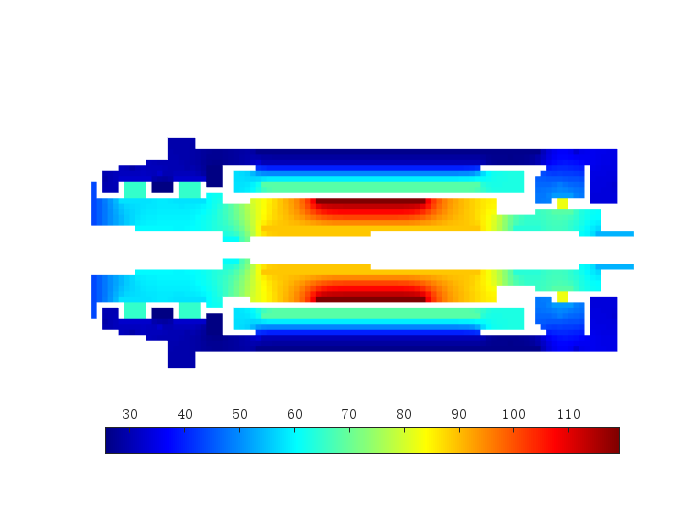

gcf=figure;
gca=pcolor(x,y,z);
set(gca, 'LineStyle','none');
axis equal;
axis off;

colormap("jet");
cbar=colorbar;
set(cbar, 'location','south','FontName','times');
imwrite(frame2im(getframe(gcf)),'spindle.bmp');